## Load Data

cd 'G:\My Drive\PhD_Research\BSF_Thesis\ModernAndSurfaceProcesses\Analyses\ModProcAnalyses\BFLATANN\Evaporation\'
cd data\input

load('Bflat30min.mat')
load('BflatEdCov.mat')
%Radiation
% figure, stackedplot(Bflat30min(:,[11,14,10,16,15,13,1]))
% title("BFLAT radiation") 

# Subset Data - Inpat ANN BFLAT variables (InputVar) and training period (subset)

% min input - humidity, temp, time of day, wind speed, radiation
InputVar = [2,3,5,6,10,11,13,15,17] %Full radiation dataset - best results

InputVar =      2     3     5     6    10    11    13    15    17


InputVarStr = ['23561011131517']; %Paired down inputs - longer radiation continuity

fullmet = table2array(Bflat30min(:,InputVar));
subset = [1:length(bflatEdCov.AirTemp1_C)];


## Training data subset


figure
% stackedplot(bflatEdCov(subset,InputVar)); 
MetTrainingData = table2array(bflatEdCov(subset,InputVar));
LEfit = bflatEdCov.Evaporation_mm30min(subset); % Eddy covariance data
LeAnnDateTime = Bflat30min.Date_Time_MDT;

% averaging = 'hourly';
% averaging = 'daily';
averaging = 'weekly';
% averaging = 'monthly';
% averaging = 'yearly';
iterations = 1000

iterations = 10000

# Do not change this part of the code - can't figure out how to make work as local function

## Loop - run model >100 times to compare the output

LeAnnModelOutput(1:length(LeAnnDateTime), 1) = [NaN]; %to make a vector of appropriate length to append to 
LeAnnModelOutputCumSum(1:length(LeAnnDateTime), 1) = [NaN]; %to make a vector of appropriate length to append to 
% LeAnnModelOutputVert(1:length(LeAnnDateTime), 1) = [NaN];
% LeAnnModelOutputVertYcolOrig = (1:length(LeAnnDateTime))';
LeAnnModelOutputCumSum(1:length(LeAnnDateTime), 1) = [NaN];
LeAnnModelOutputTrainingPeriod(1:length(MetTrainingData), 1) = [NaN]; %to make a vector of appropriate length to append to 
LeAnnModelOutputTrainingPeriodCumSum(1:length(MetTrainingData), 1) = [NaN];
for ii = 1:iterations %100 %change the number of iterations

# Automatically Generated ANN script

    % Solve an Input-Output Fitting problem with a Neural Network
    % Script generated by Neural Fitting app
    % Created 10-Mar-2020 16:18:14
    %
    % This script assumes these variables are defined:
    %
    %   datamat - input data.
    %   LEfit - target data.
    
    x = MetTrainingData';
    t = LEfit';
    
    % Choose a Training Function
    % For a list of all training functions type: help nntrain
    % 'trainlm' is usually fastest.
    % 'trainbr' takes longer but may be better for challenging problems. -
    %bayesian regularization did >400 iterations, lm only does 20-70, typically r2 above 0.92. 
    % 'trainscg' uses less memory. Suitable in low memory situations. (WORST OPTION)
    trainFcn = 'trainbr';  % Levenberg-Marquardt backpropagation.
    
    % Create a Fitting Network
    hiddenLayerSize = 10;
    net = fitnet(hiddenLayerSize,trainFcn);
    
    % Setup Division of Data for Training, Validation, Testing
    net.divideParam.trainRatio = 70/100; %switch to 70
    net.divideParam.valRatio = 30/100; %switch to 25
    net.divideParam.testRatio = 0/100;
    
    % Train the Network
    [net,tr] = train(net,x,t);
    
    % Test the Network
    y = net(x);
    e = gsubtract(t,y);
    performance = perform(net,t,y)
    
    % View the Network
    %  view(net)
    
    % Plots
    % Uncomment these lines to enable various plots.
    % figure, plotperform(tr)
    % figure, plottrainstate(tr)
    % figure, ploterrhist(e)
    %% CAN UNCOMMENT DATA WITH #
    % # plotregression(t,y)
    %# print('ModelFit','-bestfit','-dpdf') 
    %figure, plotfit(net,x,t)
    %plotfit(net,y,t)
    

### Apply to full dataset

    LEann = net(fullmet');
    LEann = LEann';
    LEann = fillmissing(LEann, "linear");
    LeAnnModelOutput = [LeAnnModelOutput, LEann];
    LeAnnModelOutputCumSum = [LeAnnModelOutputCumSum, cumsum(fillmissing(LEann, "linear"))];
    % LeAnnModelOutputVert = [LeAnnModelOutputVert; LEann];
    % LeAnnModelOutputVertYcol = [LeAnnModelOutputVertYcol; LeAnnModelOutputVertYcolOrig]; %half of what it should be.
    
    LeAnnModelOutputTrainingPeriod = [LeAnnModelOutputTrainingPeriod, y'];
    LeAnnModelOutputTrainingPeriodCumSum = [LeAnnModelOutputTrainingPeriodCumSum, cumsum(fillmissing(y', "linear"))];    
end

performance = 1.0287e-05

performance = 9.1433e-06

performance = 9.6972e-06

performance = 9.3895e-06

performance = 9.0523e-06

performance = 8.7514e-06

performance = 1.0175e-05

performance = 1.0522e-05

performance = 9.8885e-06

performance = 1.0049e-05

performance = 8.3374e-06

performance = 1.0141e-05

performance = 1.0752e-05

performance = 1.0263e-05

performance = 8.9607e-06

performance = 9.1511e-06

performance = 9.7935e-06

performance = 9.6909e-06

performance = 8.9521e-06

performance = 1.0304e-05

performance = 9.7801e-06

performance = 1.0180e-05

performance = 9.6231e-06

performance = 8.3626e-06

performance = 1.0216e-05

performance = 1.0267e-05

performance = 9.8798e-06

performance = 1.0681e-05

performance = 1.0225e-05

performance = 9.6740e-06

performance = 9.2048e-06

performance = 1.0076e-05

performance = 9.2878e-06

performance = 1.0051e-05

performance = 9.9148e-06

performance = 8.0552e-06

performance = 1.0386e-05

performance = 9.3203e-06

performance = 1.0095e-05

performance = 9.5692e-06

performance = 8.9467e-06

performance = 8.8093e-06

performance = 1.0232e-05

performance = 8.3959e-06

performance = 1.0120e-05

performance = 8.2623e-06

performance = 9.8981e-06

performance = 9.8173e-06

performance = 9.8235e-06

performance = 8.0450e-06

performance = 9.0762e-06

performance = 8.9841e-06

performance = 9.5008e-06

performance = 9.3014e-06

performance = 7.8969e-06

performance = 9.1996e-06

performance = 8.7899e-06

performance = 1.0275e-05

performance = 9.8547e-06

performance = 1.0058e-05

performance = 9.1217e-06

performance = 9.2871e-06

performance = 1.0755e-05

performance = 9.3958e-06

performance = 9.2485e-06

performance = 7.4324e-06

performance = 9.2070e-06

performance = 9.4880e-06

performance = 8.6049e-06

performance = 9.5482e-06

performance = 9.1262e-06

performance = 9.9624e-06

performance = 8.8961e-06

performance = 1.0017e-05

performance = 8.7095e-06

performance = 9.6283e-06

performance = 1.0351e-05

performance = 1.0049e-05

performance = 8.9782e-06

performance = 1.0128e-05

performance = 9.7223e-06

performance = 9.5562e-06

performance = 1.1002e-05

performance = 1.0590e-05

performance = 1.0348e-05

performance = 9.1732e-06

performance = 8.9726e-06

performance = 1.0236e-05

performance = 9.3260e-06

performance = 9.3803e-06

performance = 1.0192e-05

performance = 1.0431e-05

performance = 9.9389e-06

performance = 8.1949e-06

performance = 1.0788e-05

performance = 1.0138e-05

performance = 1.0228e-05

performance = 9.0761e-06

performance = 9.7414e-06

performance = 1.0105e-05

performance = 1.0017e-05

performance = 1.0385e-05

performance = 8.9407e-06

performance = 8.9631e-06

performance = 1.0674e-05

performance = 1.0088e-05

performance = 8.7443e-06

performance = 9.3187e-06

performance = 8.7598e-06

performance = 9.1408e-06

performance = 9.9473e-06

performance = 9.0251e-06

performance = 9.9303e-06

performance = 9.8071e-06

performance = 8.5776e-06

performance = 9.8633e-06

performance = 9.4732e-06

performance = 8.7026e-06

performance = 1.0371e-05

performance = 9.5940e-06

performance = 1.0026e-05

performance = 9.9059e-06

performance = 9.3593e-06

performance = 9.1344e-06

performance = 8.9921e-06

performance = 1.0331e-05

performance = 9.1520e-06

performance = 9.5821e-06

performance = 9.5863e-06

performance = 8.6897e-06

performance = 9.9477e-06

performance = 9.2722e-06

performance = 9.3348e-06

performance = 1.0005e-05

performance = 8.3699e-06

performance = 8.6976e-06

performance = 1.0122e-05

performance = 9.4373e-06

performance = 9.6516e-06

performance = 9.0494e-06

performance = 8.3992e-06

performance = 9.7085e-06

performance = 1.0382e-05

performance = 1.0282e-05

performance = 9.3192e-06

performance = 8.4821e-06

performance = 8.7596e-06

performance = 9.8686e-06

performance = 9.7367e-06

performance = 7.9320e-06

performance = 9.3087e-06

performance = 9.6871e-06

performance = 8.7165e-06

performance = 1.0796e-05

performance = 9.2382e-06

performance = 9.6151e-06

performance = 1.0002e-05

performance = 8.0902e-06

performance = 8.2729e-06

performance = 8.9216e-06

performance = 9.5851e-06

performance = 7.3838e-06

performance = 9.6787e-06

performance = 8.8392e-06

performance = 8.9661e-06

performance = 9.9542e-06

performance = 8.2292e-06

performance = 9.3733e-06

performance = 9.8591e-06

performance = 8.9734e-06

performance = 9.7720e-06

performance = 9.5907e-06

performance = 8.9726e-06

performance = 1.0664e-05

performance = 1.0206e-05

performance = 9.4104e-06

performance = 9.6024e-06

performance = 8.6440e-06

performance = 9.9347e-06

performance = 1.0091e-05

performance = 7.8949e-06

performance = 1.0414e-05

performance = 8.6653e-06

performance = 8.4662e-06

performance = 9.9766e-06

performance = 9.0750e-06

performance = 1.0306e-05

performance = 9.3775e-06

performance = 8.5657e-06

performance = 9.5204e-06

performance = 1.0087e-05

performance = 9.7361e-06

performance = 9.0063e-06

performance = 9.9835e-06

performance = 1.0121e-05

performance = 8.8209e-06

performance = 9.9211e-06

performance = 9.7239e-06

performance = 9.7452e-06

performance = 1.0086e-05

performance = 9.4186e-06

performance = 1.0034e-05

performance = 8.7937e-06

performance = 1.0341e-05

performance = 9.2789e-06

performance = 1.0033e-05

performance = 8.4135e-06

performance = 8.6002e-06

performance = 1.0413e-05

performance = 9.8646e-06

performance = 9.9423e-06

performance = 8.4608e-06

performance = 9.8310e-06

performance = 9.3837e-06

performance = 9.3298e-06

performance = 9.7018e-06

performance = 8.7803e-06

performance = 9.6305e-06

performance = 9.5902e-06

performance = 8.9495e-06

performance = 9.6104e-06

performance = 1.0117e-05

performance = 1.0331e-05

performance = 9.5346e-06

performance = 1.0892e-05

performance = 7.1562e-06

performance = 9.4014e-06

performance = 1.0441e-05

performance = 8.8858e-06

performance = 9.7800e-06

performance = 1.0107e-05

performance = 9.4746e-06

performance = 9.1537e-06

performance = 9.3262e-06

performance = 9.4947e-06

performance = 1.0371e-05

performance = 9.0817e-06

performance = 9.5335e-06

performance = 9.6612e-06

performance = 7.9583e-06

performance = 7.8615e-06

performance = 9.9973e-06

performance = 8.9156e-06

performance = 9.5289e-06

performance = 8.8683e-06

performance = 1.0077e-05

performance = 8.7731e-06

performance = 9.4638e-06

performance = 8.9751e-06

performance = 7.5517e-06

performance = 9.9268e-06

performance = 8.7337e-06

performance = 9.3893e-06

performance = 9.3733e-06

performance = 9.5731e-06

performance = 9.9338e-06

performance = 7.4536e-06

performance = 9.5100e-06

performance = 1.0543e-05

performance = 1.0224e-05

performance = 8.5550e-06

performance = 9.5019e-06

performance = 9.5987e-06

performance = 9.5409e-06

performance = 9.7800e-06

performance = 9.7054e-06

performance = 8.2055e-06

performance = 8.1988e-06

performance = 1.0584e-05

performance = 9.8519e-06

performance = 1.0142e-05

performance = 9.8860e-06

performance = 9.0433e-06

performance = 8.7907e-06

performance = 1.0247e-05

performance = 1.0171e-05

performance = 1.0043e-05

performance = 1.0105e-05

performance = 9.8788e-06

performance = 9.7659e-06

performance = 9.2137e-06

performance = 1.0607e-05

performance = 1.0503e-05

performance = 1.0122e-05

performance = 8.4058e-06

performance = 8.9976e-06

performance = 8.8830e-06

performance = 1.0286e-05

performance = 9.3073e-06

performance = 8.3902e-06

performance = 7.9003e-06

performance = 1.0233e-05

performance = 1.0336e-05

performance = 9.4613e-06

performance = 9.7773e-06

performance = 1.0347e-05

performance = 1.0008e-05

performance = 1.0777e-05

performance = 1.0170e-05

performance = 7.9073e-06

performance = 9.2088e-06

performance = 9.8481e-06

performance = 1.1037e-05

performance = 1.0137e-05

performance = 8.8269e-06

performance = 8.9346e-06

performance = 9.8841e-06

performance = 1.0987e-05

performance = 1.0208e-05

performance = 8.9059e-06

performance = 1.0862e-05

performance = 9.9661e-06

performance = 8.8871e-06

performance = 9.2537e-06

performance = 9.7056e-06

performance = 8.3947e-06

performance = 9.7086e-06

performance = 8.7278e-06

performance = 9.7566e-06

performance = 7.7530e-06

performance = 1.0187e-05

performance = 9.5032e-06

performance = 9.7404e-06

performance = 9.7442e-06

performance = 1.0070e-05

performance = 9.6694e-06

performance = 8.8147e-06

performance = 9.8320e-06

performance = 1.0529e-05

performance = 8.5671e-06

performance = 1.0037e-05

performance = 1.0638e-05

performance = 8.5663e-06

performance = 9.0774e-06

performance = 8.6881e-06

performance = 1.0046e-05

performance = 9.0692e-06

performance = 9.1347e-06

performance = 8.3039e-06

performance = 9.6903e-06

performance = 8.0010e-06

performance = 9.8151e-06

performance = 9.2642e-06

performance = 1.0209e-05

performance = 7.1915e-06

performance = 9.3615e-06

performance = 7.5691e-06

performance = 1.0396e-05

performance = 1.0524e-05

performance = 9.0329e-06

performance = 9.2568e-06

performance = 9.6335e-06

performance = 8.4970e-06

performance = 9.5133e-06

performance = 9.8611e-06

performance = 1.0319e-05

performance = 9.4062e-06

performance = 1.0571e-05

performance = 9.7713e-06

performance = 1.0093e-05

performance = 8.5737e-06

performance = 8.5505e-06

performance = 9.9320e-06

performance = 9.3737e-06

performance = 8.1288e-06

performance = 8.5263e-06

performance = 8.8374e-06

performance = 1.0306e-05

performance = 1.0174e-05

performance = 1.0768e-05

performance = 9.3822e-06

performance = 8.4447e-06

performance = 8.7118e-06

performance = 1.0825e-05

performance = 9.6648e-06

performance = 9.5931e-06

performance = 8.8890e-06

performance = 9.1262e-06

performance = 8.9049e-06

performance = 1.0110e-05

performance = 9.4479e-06

performance = 1.0185e-05

performance = 9.8017e-06

performance = 1.0686e-05

performance = 9.4307e-06

performance = 9.1001e-06

performance = 1.0187e-05

performance = 8.9601e-06

performance = 9.9820e-06

performance = 9.2830e-06

performance = 9.6913e-06

performance = 9.2526e-06

performance = 1.0385e-05

performance = 9.0749e-06

performance = 1.0112e-05

performance = 1.0449e-05

performance = 9.4212e-06

performance = 9.6241e-06

performance = 8.7985e-06

performance = 8.8484e-06

performance = 1.0887e-05

performance = 9.8133e-06

performance = 1.0185e-05

performance = 1.0635e-05

performance = 9.6585e-06

performance = 9.3889e-06

performance = 1.0386e-05

performance = 9.9568e-06

performance = 1.0082e-05

performance = 1.0399e-05

performance = 1.0127e-05

performance = 9.8861e-06

performance = 9.5570e-06

performance = 8.0587e-06

performance = 9.3778e-06

performance = 9.3892e-06

performance = 9.7607e-06

performance = 9.4944e-06

performance = 9.8110e-06

performance = 1.0211e-05

performance = 9.7036e-06

performance = 1.0088e-05

performance = 9.7801e-06

performance = 9.4229e-06

performance = 8.8065e-06

performance = 9.2908e-06

performance = 9.7361e-06

performance = 9.2854e-06

performance = 1.0538e-05

performance = 9.6375e-06

performance = 1.0260e-05

performance = 9.5562e-06

performance = 1.0209e-05

performance = 9.1500e-06

performance = 9.6677e-06

performance = 8.2728e-06

performance = 1.0033e-05

performance = 9.3664e-06

performance = 9.8787e-06

performance = 9.5821e-06

performance = 1.0392e-05

performance = 9.7800e-06

performance = 8.1732e-06

performance = 1.0322e-05

performance = 9.0875e-06

performance = 9.9165e-06

performance = 8.9103e-06

performance = 8.0295e-06

performance = 9.1226e-06

performance = 1.0097e-05

performance = 8.7551e-06

performance = 1.0134e-05

performance = 9.2669e-06

performance = 8.8155e-06

performance = 9.3349e-06

performance = 1.0053e-05

performance = 9.6385e-06

performance = 9.1343e-06

performance = 1.0344e-05

performance = 9.2375e-06

performance = 9.4117e-06

performance = 8.8853e-06

performance = 9.9466e-06

performance = 1.0093e-05

performance = 8.6617e-06

performance = 9.2381e-06

performance = 9.2218e-06

performance = 9.9534e-06

performance = 1.0476e-05

performance = 9.2361e-06

performance = 1.0274e-05

performance = 9.3252e-06

performance = 9.3093e-06

performance = 1.0624e-05

performance = 9.6280e-06

performance = 9.4718e-06

performance = 9.1994e-06

performance = 9.4381e-06

performance = 1.0104e-05

performance = 9.0919e-06

performance = 1.0209e-05

performance = 8.8660e-06

performance = 9.3830e-06

performance = 8.6930e-06

performance = 9.6219e-06

performance = 1.0141e-05

performance = 9.7801e-06

performance = 9.7361e-06

performance = 8.5060e-06

performance = 9.3737e-06

performance = 9.1059e-06

performance = 9.5911e-06

performance = 8.7887e-06

performance = 9.4574e-06

performance = 9.8399e-06

performance = 9.4754e-06

performance = 1.0079e-05

performance = 9.6916e-06

performance = 9.0920e-06

performance = 8.6211e-06

performance = 7.4478e-06

performance = 1.0715e-05

performance = 1.0448e-05

performance = 9.3539e-06

performance = 7.2817e-06

performance = 9.6206e-06

performance = 9.1189e-06

performance = 1.1292e-05

performance = 9.5353e-06

performance = 9.9081e-06

performance = 9.5061e-06

performance = 9.0200e-06

performance = 8.3729e-06

performance = 1.0878e-05

performance = 9.9720e-06

performance = 8.5757e-06

performance = 1.0180e-05

performance = 8.9209e-06

performance = 8.1975e-06

performance = 9.4802e-06

performance = 8.7440e-06

performance = 8.7780e-06

performance = 9.5264e-06

performance = 7.7769e-06

performance = 9.7852e-06

performance = 9.8450e-06

performance = 8.7429e-06

performance = 9.7590e-06

performance = 9.7098e-06

performance = 9.2915e-06

performance = 9.6208e-06

performance = 9.9481e-06

performance = 8.9310e-06

performance = 8.3877e-06

performance = 9.8135e-06

performance = 9.1025e-06

performance = 9.9584e-06

performance = 8.2347e-06

performance = 8.6366e-06

performance = 9.3899e-06

performance = 8.5670e-06

performance = 1.0337e-05

performance = 8.9324e-06

performance = 9.3295e-06

performance = 9.4882e-06

performance = 1.0493e-05

performance = 8.2621e-06

performance = 9.4329e-06

performance = 8.6569e-06

performance = 9.1420e-06

performance = 1.0129e-05

performance = 9.6464e-06

performance = 8.9991e-06

performance = 1.0065e-05

performance = 1.0136e-05

performance = 8.7006e-06

performance = 1.0382e-05

performance = 9.2968e-06

performance = 8.9521e-06

performance = 1.0465e-05

performance = 1.0582e-05

performance = 9.8575e-06

performance = 9.8880e-06

performance = 9.4343e-06

performance = 9.8467e-06

performance = 9.0242e-06

performance = 9.2619e-06

performance = 9.4211e-06

performance = 8.6612e-06

performance = 1.0153e-05

performance = 1.0666e-05

performance = 8.5850e-06

performance = 8.3664e-06

performance = 9.1381e-06

performance = 8.8856e-06

performance = 1.0322e-05

performance = 8.3587e-06

performance = 1.0073e-05

performance = 1.0313e-05

performance = 9.8882e-06

performance = 9.7570e-06

performance = 9.8766e-06

performance = 8.5978e-06

performance = 9.9664e-06

performance = 9.5310e-06

performance = 1.0949e-05

performance = 9.5032e-06

performance = 9.3989e-06

performance = 9.0553e-06

performance = 1.0044e-05

performance = 1.0457e-05

performance = 9.7810e-06

performance = 1.0835e-05

performance = 8.3830e-06

performance = 8.5459e-06

performance = 9.7678e-06

performance = 9.2013e-06

performance = 9.7572e-06

performance = 9.7801e-06

performance = 9.9860e-06

performance = 9.3385e-06

performance = 9.1267e-06

performance = 8.3960e-06

performance = 1.0522e-05

performance = 1.0273e-05

performance = 8.6957e-06

performance = 9.5236e-06

performance = 8.6185e-06

performance = 1.0230e-05

performance = 7.5871e-06

performance = 9.3149e-06

performance = 9.4231e-06

performance = 9.7921e-06

performance = 1.1062e-05

performance = 1.0641e-05

performance = 7.8349e-06

performance = 9.6489e-06

performance = 8.5781e-06

performance = 9.5176e-06

performance = 9.7959e-06

performance = 1.0579e-05

performance = 1.0062e-05

performance = 1.0008e-05

performance = 9.1250e-06

performance = 1.0021e-05

performance = 9.2773e-06

performance = 1.0134e-05

performance = 9.7430e-06

performance = 9.4787e-06

performance = 9.5571e-06

performance = 1.0329e-05

performance = 9.6930e-06

performance = 9.6308e-06

performance = 9.4868e-06

performance = 8.4905e-06

performance = 9.9792e-06

performance = 1.0954e-05

performance = 1.0107e-05

performance = 9.9419e-06

performance = 9.8045e-06

performance = 8.8237e-06

performance = 8.4670e-06

performance = 9.4866e-06

performance = 1.0479e-05

performance = 1.0036e-05

performance = 9.7704e-06

performance = 9.8039e-06

performance = 9.3883e-06

performance = 1.0063e-05

performance = 9.4687e-06

performance = 1.0508e-05

performance = 9.3951e-06

performance = 8.6658e-06

performance = 9.0368e-06

performance = 9.7096e-06

performance = 8.5408e-06

performance = 9.1102e-06

performance = 1.0550e-05

performance = 1.1126e-05

performance = 1.0097e-05

performance = 8.7844e-06

performance = 1.0035e-05

performance = 8.6013e-06

performance = 1.0158e-05

performance = 9.5994e-06

performance = 9.1558e-06

performance = 9.9880e-06

performance = 9.8522e-06

performance = 8.8908e-06

performance = 8.2258e-06

performance = 9.3399e-06

performance = 9.6481e-06

performance = 7.1852e-06

performance = 1.0167e-05

performance = 8.6312e-06

performance = 1.0082e-05

performance = 9.4882e-06

performance = 9.2395e-06

performance = 1.0398e-05

performance = 1.0690e-05

performance = 1.0100e-05

performance = 8.6746e-06

performance = 8.5822e-06

performance = 9.3082e-06

performance = 1.0183e-05

performance = 9.9456e-06

performance = 9.7013e-06

performance = 8.4905e-06

performance = 8.6236e-06

performance = 1.0314e-05

performance = 9.8784e-06

performance = 8.6930e-06

performance = 9.9021e-06

performance = 1.0404e-05

performance = 8.2685e-06

performance = 8.4662e-06

performance = 9.7011e-06

performance = 9.4018e-06

performance = 9.1154e-06

performance = 7.5808e-06

performance = 1.0316e-05

performance = 9.8965e-06

performance = 9.5280e-06

performance = 1.0356e-05

performance = 7.8794e-06

performance = 9.7766e-06

performance = 1.0328e-05

performance = 1.0092e-05

performance = 9.7719e-06

performance = 9.7436e-06

performance = 9.6858e-06

performance = 9.3939e-06

performance = 8.6671e-06

performance = 9.0980e-06

performance = 8.3063e-06

performance = 1.1149e-05

performance = 1.0365e-05

performance = 1.0049e-05

performance = 9.5222e-06

performance = 8.1202e-06

performance = 9.4117e-06

performance = 1.0271e-05

performance = 1.0106e-05

performance = 8.9165e-06

performance = 9.7834e-06

performance = 9.5746e-06

performance = 9.3523e-06

performance = 9.7033e-06

performance = 9.1271e-06

performance = 9.8195e-06

performance = 8.1376e-06

performance = 1.0732e-05

performance = 1.0387e-05

performance = 1.0591e-05

performance = 9.8976e-06

performance = 7.5545e-06

performance = 9.6309e-06

performance = 8.7760e-06

performance = 9.1417e-06

performance = 9.8448e-06

performance = 8.4417e-06

performance = 9.8786e-06

performance = 8.8455e-06

performance = 7.6927e-06

performance = 9.7812e-06

performance = 1.0156e-05

performance = 1.0924e-05

performance = 1.0292e-05

performance = 8.7141e-06

performance = 9.6274e-06

performance = 8.7687e-06

performance = 7.1854e-06

performance = 9.3081e-06

performance = 1.0248e-05

performance = 9.4195e-06

performance = 9.7298e-06

performance = 8.1429e-06

performance = 1.0862e-05

performance = 9.9736e-06

performance = 9.6281e-06

performance = 9.7069e-06

performance = 9.0094e-06

performance = 9.9063e-06

performance = 8.5925e-06

performance = 1.0985e-05

performance = 1.0495e-05

performance = 9.2305e-06

performance = 9.9007e-06

performance = 9.3434e-06

performance = 9.7833e-06

performance = 1.0131e-05

performance = 9.2206e-06

performance = 9.9658e-06

performance = 9.0706e-06

performance = 1.0493e-05

performance = 9.8724e-06

performance = 9.4939e-06

performance = 8.9789e-06

performance = 1.0518e-05

performance = 8.5971e-06

performance = 9.5247e-06

performance = 9.4749e-06

performance = 1.0339e-05

performance = 7.3999e-06

performance = 9.7390e-06

performance = 1.0068e-05

performance = 9.0936e-06

performance = 9.4638e-06

performance = 8.7495e-06

performance = 1.0438e-05

performance = 8.8477e-06

performance = 1.0525e-05

performance = 1.0106e-05

performance = 9.1482e-06

performance = 9.7800e-06

performance = 8.7402e-06

performance = 8.4858e-06

performance = 8.9167e-06

performance = 1.1197e-05

performance = 9.0509e-06

performance = 1.0648e-05

performance = 1.0732e-05

performance = 9.1641e-06

performance = 9.9909e-06

performance = 9.0914e-06

performance = 1.1034e-05

performance = 1.0308e-05

performance = 9.1155e-06

performance = 9.9341e-06

performance = 7.8662e-06

performance = 9.6336e-06

performance = 7.8378e-06

performance = 9.6932e-06

performance = 9.5153e-06

performance = 1.1261e-05

performance = 8.7120e-06

performance = 9.3269e-06

performance = 9.1524e-06

performance = 1.1114e-05

performance = 9.5063e-06

performance = 9.8764e-06

performance = 9.9885e-06

performance = 9.7457e-06

performance = 9.5353e-06

performance = 9.7802e-06

performance = 1.0577e-05

performance = 1.0704e-05

performance = 8.5335e-06

performance = 9.6435e-06

performance = 1.0660e-05

performance = 1.1219e-05

performance = 9.8457e-06

performance = 1.0338e-05

performance = 9.2747e-06

performance = 8.8223e-06

performance = 8.7765e-06

performance = 9.8221e-06

performance = 9.9645e-06

performance = 1.0110e-05

performance = 9.9753e-06

performance = 8.3397e-06

performance = 9.8259e-06

performance = 1.0615e-05

performance = 1.0509e-05

performance = 1.0229e-05

performance = 9.3126e-06

performance = 1.0064e-05

performance = 9.8266e-06

performance = 9.9372e-06

performance = 9.9596e-06

performance = 1.0025e-05

performance = 1.0253e-05

performance = 1.0321e-05

performance = 8.3287e-06

performance = 8.5823e-06

performance = 9.3204e-06

performance = 9.7800e-06

performance = 1.0012e-05

performance = 8.9353e-06

performance = 1.0033e-05

performance = 1.1103e-05

performance = 1.0024e-05

performance = 8.2815e-06

performance = 1.0434e-05

performance = 8.9827e-06

performance = 8.9998e-06

performance = 9.1924e-06

performance = 9.2067e-06

performance = 9.7741e-06

performance = 7.8317e-06

performance = 1.0512e-05

performance = 9.2295e-06

performance = 8.6386e-06

performance = 9.7008e-06

performance = 9.6191e-06

performance = 9.3385e-06

performance = 9.4713e-06

performance = 8.5504e-06

performance = 8.8730e-06

performance = 8.3310e-06

performance = 9.9205e-06

performance = 9.3354e-06

performance = 1.0061e-05

performance = 9.1164e-06

performance = 1.0522e-05

performance = 9.7452e-06

performance = 8.5414e-06

performance = 8.1001e-06

performance = 8.0287e-06

performance = 9.5224e-06

performance = 1.0084e-05

performance = 1.0711e-05

performance = 1.0117e-05

performance = 1.0198e-05

performance = 9.7766e-06

performance = 9.5021e-06

performance = 8.6372e-06

performance = 1.0011e-05

performance = 9.2496e-06

performance = 9.2447e-06

performance = 8.7271e-06

performance = 9.6424e-06

performance = 9.6455e-06

performance = 9.0364e-06

performance = 9.9139e-06

performance = 9.7037e-06

performance = 8.6085e-06

performance = 9.6282e-06

performance = 9.5442e-06

performance = 1.0379e-05

performance = 8.5418e-06

performance = 9.8299e-06

performance = 1.0232e-05

performance = 1.0241e-05

performance = 9.8717e-06

performance = 9.2660e-06

performance = 9.6431e-06

performance = 9.5693e-06

performance = 9.7173e-06

performance = 9.4618e-06

performance = 1.0460e-05

performance = 8.3391e-06

performance = 7.6984e-06

performance = 9.3519e-06

performance = 8.5909e-06

performance = 1.0303e-05

performance = 9.3175e-06

performance = 1.0042e-05

performance = 1.0205e-05

performance = 9.2538e-06

performance = 8.6679e-06

performance = 9.0756e-06

performance = 9.6369e-06

performance = 9.9603e-06

performance = 9.0041e-06

performance = 9.0967e-06

performance = 9.1711e-06

performance = 8.9440e-06

performance = 9.7558e-06

performance = 8.6809e-06

performance = 9.5683e-06

performance = 8.0663e-06

performance = 9.4024e-06

performance = 9.6246e-06

performance = 9.4371e-06

performance = 9.6578e-06

performance = 9.2163e-06

performance = 7.9987e-06

performance = 1.0595e-05

performance = 9.9497e-06

performance = 1.0600e-05

performance = 1.0553e-05

performance = 9.4687e-06

performance = 9.6205e-06

performance = 9.4940e-06

performance = 1.0207e-05

performance = 9.4046e-06

performance = 1.0292e-05

performance = 9.1719e-06

performance = 9.6935e-06

performance = 8.9281e-06

performance = 1.0450e-05

performance = 8.8261e-06

performance = 9.8431e-06

performance = 9.5065e-06

performance = 1.0054e-05

performance = 8.4663e-06

performance = 9.8801e-06

performance = 9.1132e-06

performance = 1.0290e-05

performance = 9.7027e-06

performance = 9.9498e-06

performance = 8.9801e-06

performance = 9.9599e-06

performance = 1.0181e-05

performance = 1.0223e-05

performance = 8.8606e-06

performance = 9.8957e-06

performance = 8.9400e-06

performance = 9.9365e-06

performance = 7.5316e-06

performance = 1.0775e-05

performance = 7.6039e-06

performance = 9.6911e-06

performance = 8.9735e-06

performance = 9.5275e-06

performance = 9.6789e-06

performance = 8.6822e-06

performance = 9.4928e-06

performance = 9.7801e-06

performance = 9.6704e-06

performance = 9.3431e-06

performance = 1.0236e-05

performance = 1.0064e-05

performance = 9.4386e-06

performance = 9.8499e-06

performance = 9.5900e-06

performance = 9.7454e-06

performance = 8.9794e-06

performance = 9.7959e-06

performance = 9.3496e-06

performance = 9.0422e-06

performance = 9.0366e-06

performance = 1.0033e-05

performance = 9.6601e-06

performance = 1.0150e-05

performance = 9.8496e-06

performance = 1.0303e-05

performance = 1.0080e-05

performance = 1.0531e-05

performance = 9.2645e-06

performance = 1.0475e-05

performance = 1.0591e-05

performance = 9.7139e-06

performance = 1.0638e-05

performance = 8.6771e-06

performance = 9.6163e-06

performance = 1.0656e-05

performance = 9.6324e-06

performance = 8.8862e-06

performance = 9.4183e-06

performance = 1.0853e-05

performance = 8.1141e-06

performance = 9.6865e-06

performance = 6.9319e-06

performance = 7.9626e-06

performance = 8.7794e-06

performance = 9.0385e-06

performance = 9.0759e-06

performance = 9.0067e-06

performance = 7.8849e-06

performance = 1.0084e-05

performance = 9.2341e-06

performance = 8.6710e-06

performance = 9.1256e-06

performance = 8.5096e-06

performance = 8.9989e-06

performance = 9.7105e-06

performance = 9.4552e-06

performance = 9.8640e-06

performance = 7.6011e-06

performance = 1.0611e-05

performance = 8.5371e-06

performance = 8.9919e-06

performance = 9.8000e-06

performance = 9.3617e-06

performance = 8.3592e-06

performance = 8.9381e-06

performance = 9.1718e-06

performance = 9.5520e-06

performance = 9.9425e-06

performance = 8.4051e-06

performance = 1.1293e-05

performance = 9.5729e-06

performance = 9.4062e-06

performance = 9.4892e-06

performance = 9.9497e-06

performance = 9.9448e-06

performance = 9.7138e-06

performance = 9.9631e-06

performance = 9.5915e-06

performance = 1.0380e-05

performance = 9.6443e-06

performance = 1.0021e-05

performance = 1.0399e-05

performance = 8.9651e-06

performance = 8.1979e-06

performance = 8.8876e-06

performance = 9.8903e-06

performance = 9.6406e-06

performance = 9.3360e-06

performance = 1.0079e-05

performance = 8.9141e-06

performance = 9.8717e-06

performance = 9.8612e-06

performance = 1.1073e-05

performance = 9.7153e-06

performance = 8.5660e-06

performance = 1.0342e-05

performance = 9.9490e-06

performance = 9.5321e-06

performance = 1.0534e-05

performance = 9.9184e-06

performance = 1.0557e-05

performance = 9.2391e-06

performance = 8.9900e-06

performance = 9.3040e-06

performance = 9.3180e-06

performance = 1.0298e-05

performance = 9.5146e-06

performance = 9.3267e-06

performance = 9.2290e-06

performance = 9.4125e-06

performance = 8.7741e-06

performance = 9.5787e-06

performance = 1.0329e-05

performance = 9.6504e-06

performance = 1.0281e-05

performance = 9.4300e-06

performance = 1.0296e-05

performance = 9.1903e-06

performance = 9.8303e-06

performance = 8.5747e-06

performance = 9.8338e-06

performance = 9.8210e-06

performance = 9.6958e-06

performance = 1.0420e-05

performance = 1.0851e-05

performance = 9.6894e-06

performance = 8.9997e-06

performance = 9.6022e-06

performance = 9.3947e-06

performance = 9.5214e-06

performance = 8.6838e-06

performance = 1.0132e-05

performance = 1.0094e-05

performance = 8.5352e-06

performance = 1.0001e-05

performance = 1.0061e-05

performance = 1.0726e-05

performance = 1.0156e-05

performance = 7.5391e-06

performance = 1.0251e-05

performance = 1.0314e-05

performance = 1.0084e-05

performance = 9.8393e-06

performance = 9.6154e-06

performance = 1.0815e-05

performance = 9.7361e-06

performance = 9.6079e-06

performance = 9.9749e-06

performance = 1.0250e-05

performance = 1.0043e-05

performance = 9.4241e-06

performance = 9.3970e-06

performance = 8.4370e-06

performance = 9.7956e-06

performance = 1.0065e-05

performance = 1.0173e-05

performance = 9.8199e-06

performance = 1.0090e-05

performance = 9.6720e-06

performance = 1.0316e-05

performance = 8.3610e-06

performance = 9.1605e-06

performance = 8.4674e-06

performance = 9.8347e-06

performance = 1.0422e-05

performance = 9.2081e-06

performance = 8.4219e-06

performance = 9.7515e-06

performance = 9.6722e-06

performance = 9.4743e-06

performance = 9.1904e-06

performance = 9.0409e-06

performance = 8.5804e-06

performance = 1.0709e-05

performance = 7.9360e-06

performance = 9.5985e-06

performance = 9.1205e-06

performance = 7.2709e-06

performance = 9.8610e-06

performance = 9.0963e-06

performance = 9.7765e-06

performance = 9.5397e-06

performance = 9.1066e-06

performance = 1.0236e-05

performance = 1.0595e-05

performance = 1.0221e-05

performance = 8.8426e-06

performance = 1.0096e-05

performance = 1.1136e-05

performance = 1.0514e-05

performance = 1.0492e-05

performance = 8.6022e-06

performance = 8.8915e-06

performance = 9.7845e-06

performance = 8.9210e-06

performance = 9.0585e-06

performance = 9.8014e-06

performance = 1.0359e-05

performance = 8.6779e-06

performance = 1.0908e-05

performance = 8.5662e-06

performance = 9.7757e-06

performance = 9.8814e-06

performance = 8.1997e-06

performance = 1.0341e-05

performance = 8.5291e-06

performance = 9.4275e-06

performance = 7.2745e-06

performance = 9.4509e-06

performance = 8.4270e-06

performance = 9.8413e-06

performance = 9.5991e-06

performance = 8.9506e-06

performance = 9.9567e-06

performance = 9.5219e-06

performance = 9.6358e-06

performance = 8.9892e-06

performance = 1.0339e-05

performance = 9.3072e-06

performance = 9.2698e-06

performance = 8.0754e-06

performance = 9.2147e-06

performance = 1.0729e-05

performance = 9.8500e-06

performance = 1.0402e-05

performance = 1.0191e-05

performance = 9.9696e-06

performance = 1.0049e-05

performance = 9.6464e-06

## Compare fit quality 

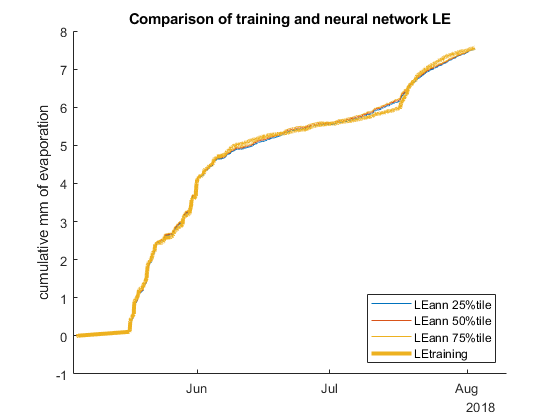

clear y performance x hiddenLayerSize trainFcn tr LEann e t ii net
LeAnnModelOutputTrainingPeriod(:,1) = [];
% LeAnnModelOutputTrainingPeriod = transpose(mean(transpose(LeAnnModelOutputTrainingPeriod)));
LeAnnModelOutputTrainingPeriodCumSum50 = prctile((LeAnnModelOutputTrainingPeriodCumSum(:,1:end)),[50],2); %maywanttoreconsider naming here
LeAnnModelOutputTrainingPeriodCumSum25 = prctile((LeAnnModelOutputTrainingPeriodCumSum(:,1:end)),[25],2); %maywanttoreconsider naming here
LeAnnModelOutputTrainingPeriodCumSum75 = prctile((LeAnnModelOutputTrainingPeriodCumSum(:,1:end)),[75],2); %maywanttoreconsider naming here

figure
hold on
plot(bflatEdCov.Date_Time_MDT, LeAnnModelOutputTrainingPeriodCumSum25, 'DisplayName', 'LEann 25%tile')
plot(bflatEdCov.Date_Time_MDT, LeAnnModelOutputTrainingPeriodCumSum50, 'DisplayName', 'LEann 50%tile')
plot(bflatEdCov.Date_Time_MDT, LeAnnModelOutputTrainingPeriodCumSum75, 'DisplayName', 'LEann 75%tile')
plot(bflatEdCov.Date_Time_MDT, cumsum(fillmissing(bflatEdCov.Evaporation_mm30min(subset), "linear")), ...
    'color', [0.9290 0.6940 0.1250],'linewidth', 3,  'DisplayName','LEtraining')
legend('location', 'southeast')
ylabel("cumulative mm of evaporation")
title('Comparison of training and neural network LE')

## Show that need to select the cumsum value... better - we bias the quartiles wide when we do this - so need to do the lower and higher data differently

Bflat30min(:,2:end) = [];
Bflat30min.LEann_mean = transpose(mean(transpose(LeAnnModelOutput(:,2:end))));
% Bflat30min.LEann_std = transpose(std(transpose(LeAnnModelOutput(:,2:end))));
Bflat30min.LEann_prctile50 = prctile((LeAnnModelOutput(:,2:end)),[50],2); %calculate percentiles
Bflat30min.LEann_prctile50cumsum = cumsum((fillmissing(Bflat30min.LEann_prctile50, "linear")));

clear LeAnnModelOutputTrainingPeriodCumSum75 LeAnnModelOutputTrainingPeriodCumSum50 LeAnnModelOutputTrainingPeriodCumSum25

## OUTPUT = LEann calculated for entire dataset

Bflat30min(:,2:end) = [];
Bflat30min.LEann_mean = transpose(mean(transpose(LeAnnModelOutput(:,2:end))));
Bflat30min.LEann_prctile50 = prctile((LeAnnModelOutput(:,2:end)),[50],2); %calculate percentiles

% Bflat30min.LEann_IQR = prctile((LeAnnModelOutput(:,2:end)),[75],2) - prctile((LeAnnModelOutput(:,2:end)),[25],2); %calculate percentiles


#### Calculate the 25th percetile column

Bflat30min.LEann_prctile25 = prctile((LeAnnModelOutput(:,2:end)),[25],2);
Bflat30min.LEann_prctile75 = prctile((LeAnnModelOutput(:,2:end)),[75],2);

Bflat30min.LEann_CumSum_mean = transpose(mean(transpose(LeAnnModelOutputCumSum(:,2:end))));
Bflat30min.LEann_CumSum_prctile50 = prctile((LeAnnModelOutputCumSum(:,2:end)),[50],2); 


tile25column = prctile(LeAnnModelOutputCumSum(end, 1:end), 25, 2) %determine the 25th percentile value(s). 

tile25column = 379.5554

[tile25column] = find(LeAnnModelOutputCumSum(end, :) > (tile25column - 15) & LeAnnModelOutputCumSum(end, :) < (tile25column + 15)) %find the column(s) with the 25th percentile value(s) 

tile25column =           94         281         368         736         835        1203


tile25column = tile25column(1) %number of the column with the 25th percentile value for cumulative sum. 

tile25column = 94

Bflat30min.LEann_prctile25singlemodel = LeAnnModelOutput(:,tile25column); %save this column (from the original non-cumulative file) to the output file. 
Bflat30min.LEann_CumSum_prctile25 = cumsum(Bflat30min.LEann_prctile25singlemodel); %calculate the cumulative sum of this new file. 


#### Calculate the 75th percetile column

tile75column = prctile(LeAnnModelOutputCumSum(end, 1:end), 75, 2)

tile75column = 694.4501

[tile75column] = find(LeAnnModelOutputCumSum(end, :) > (tile75column - 15) & LeAnnModelOutputCumSum(end, :) < (tile75column + 15))

tile75column =          595        1062


tile75column = tile75column(1)

tile75column = 595

Bflat30min.LEann_prctile75singlemodel = LeAnnModelOutput(:,tile75column);
Bflat30min.LEann_CumSum_prctile75 = cumsum(Bflat30min.LEann_prctile75singlemodel);

Bflat30min(:,1) = [];

### Effect of changing different study periods

BFLATnew = retime(Bflat30min, averaging, 'mean');

### Percentile seems effective, but large difference between 50th percentile and mean

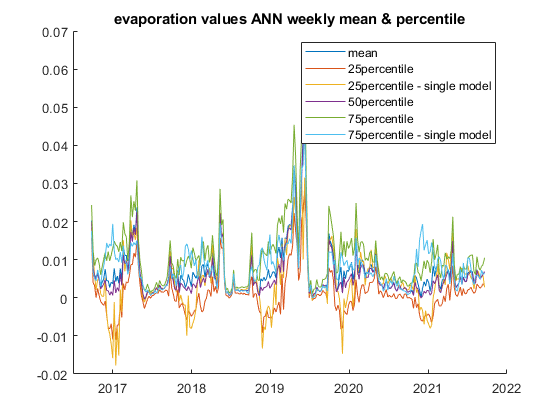

figure
hold on 

plot(BFLATnew.Date_Time_MDT, BFLATnew.LEann_mean, 'DisplayName', 'mean')
plot(BFLATnew.Date_Time_MDT, BFLATnew.LEann_prctile25, 'DisplayName', '25percentile')
plot(BFLATnew.Date_Time_MDT, BFLATnew.LEann_prctile25singlemodel, 'DisplayName', '25percentile - single model')
plot(BFLATnew.Date_Time_MDT, BFLATnew.LEann_prctile50, 'DisplayName', '50percentile')
plot(BFLATnew.Date_Time_MDT, BFLATnew.LEann_prctile75, 'DisplayName', '75percentile')
plot(BFLATnew.Date_Time_MDT, BFLATnew.LEann_prctile75singlemodel, 'DisplayName', '75percentile - single model')

legend
title(['evaporation values ANN ',averaging,' mean & percentile'])
hold off

### Show cumulative sum of weekly averages?  title(['evaporation values ANN ',averaging,' averages'])

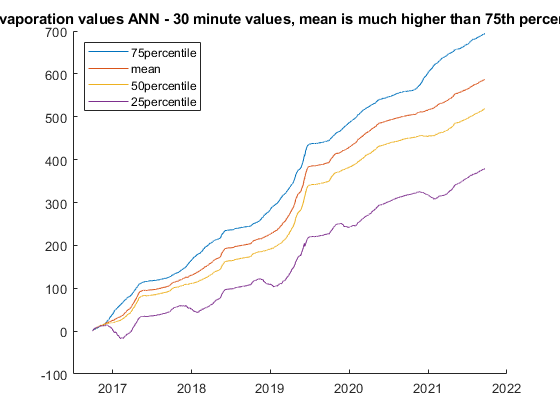

figure
hold on 
plot(Bflat30min.Date_Time_MDT, Bflat30min.LEann_CumSum_prctile75, 'DisplayName', '75percentile')
plot(Bflat30min.Date_Time_MDT, Bflat30min.LEann_CumSum_mean, 'DisplayName', 'mean')
plot(Bflat30min.Date_Time_MDT, Bflat30min.LEann_CumSum_prctile50, 'DisplayName', '50percentile')
plot(Bflat30min.Date_Time_MDT, Bflat30min.LEann_CumSum_prctile25, 'DisplayName', '25percentile')
legend('location', 'northwest')
title("evaporation values ANN - 30 minute values, mean is much higher than 75th percentile")
hold off

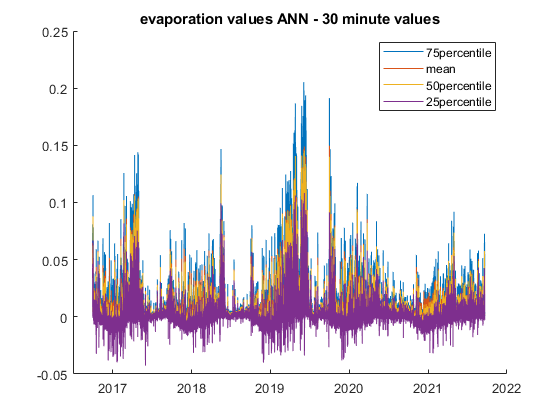


figure
hold on 
plot(Bflat30min.Date_Time_MDT, Bflat30min.LEann_prctile75, 'DisplayName', '75percentile')
plot(Bflat30min.Date_Time_MDT, Bflat30min.LEann_mean, 'DisplayName', 'mean')
plot(Bflat30min.Date_Time_MDT, Bflat30min.LEann_prctile50, 'DisplayName', '50percentile')
plot(Bflat30min.Date_Time_MDT, Bflat30min.LEann_prctile25, 'DisplayName', '25percentile')
legend
title("evaporation values ANN - 30 minute values")
hold off

% figure
% plot(Bflat30min.Date_Time_MDT, Bflat30min.LEann_IQR)
% title("IQR over time")

% clear bflatEdCov fullmet InputVar LeAnnDateTime LeAnnModelOutput LeAnnModelOutputCumSum 
% clear LeAnnModelOutputTrainingPeriodCumSum LeAnnModelOutputTrainingPeriod LEfit
% clear OUTPUT MetTrainingData subset


# Save Data - adjust the input parameters!

cd ../output/
eval(['Bflat_30minLEann_',InputVarStr, ' = Bflat30min;'])
eval (['BFLAT_', averaging, 'LEann_', InputVarStr,' = BFLATnew;'])
InputVarStr;

#### Automate this part - for now make sure the interval and input variables are correct

% writetimetable(Bflat_30minLEann_23561011131517)
save('Bflat_30minLEann_23561011131517.mat','Bflat_30minLEann_23561011131517')

% writetimetable(BFLAT_weeklyLEann_23561011131517)
save('BFLAT_weeklyLEann_23561011131517.mat','BFLAT_weeklyLEann_23561011131517')